# Alinea A

N = 1e5;
lancamentos = 4;
experiencias = rand(4,N);
coroa = experiencias > 0.5; % 1 = coroa
numCoroas = sum(coroa);

sair_0Coroa = sum(numCoroas == 0)/N

sair_0Coroa = 0.0615

sair_1Coroa = sum(numCoroas == 1)/N

sair_1Coroa = 0.2511

sair_2Coroa = sum(numCoroas == 2)/N

sair_2Coroa = 0.3764

sair_3Coroa = sum(numCoroas == 3)/N

sair_3Coroa = 0.2482

sair_4Coroa = sum(numCoroas == 4)/N

sair_4Coroa = 0.0628

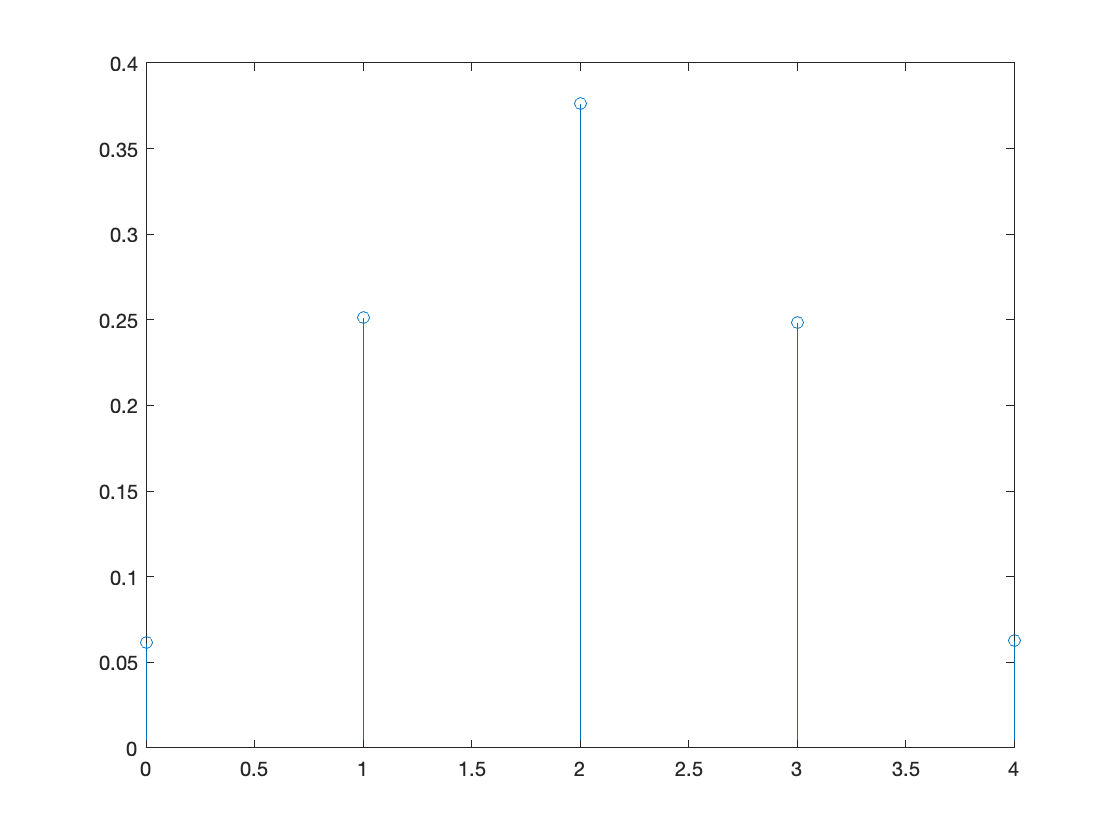




stem((0:4), [sair_0Coroa sair_1Coroa sair_2Coroa sair_3Coroa sair_4Coroa])

## Alinea B

X = (0:4);

px = [sair_0Coroa sair_1Coroa sair_2Coroa sair_3Coroa sair_4Coroa];

valorEsperado = sum(X.*px)

valorEsperado = 1.9999


variancia = 0;
for i = 0:4
    variancia = variancia + (((i - valorEsperado)^2) * px(i + 1));
end

variancia

variancia = 0.9965

desviopadrao = sqrt(variancia)

desviopadrao = 0.9983